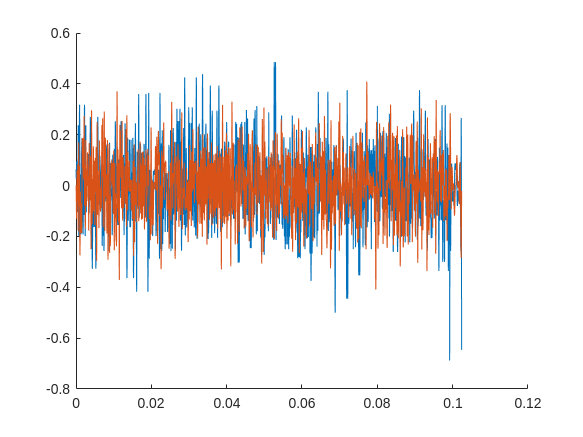

% Adam Nichols
% Prof. Jacobs
% ECE 1898
% 3 February 2025

% modulate/demodulate a message using a simple OFDM scheme

% reset the workspace
clear, clc

% generate a message of random bits
num_bits = 1000;
bits = RandomBits(num_bits);

% parallelize bits into bitstreams
num_carriers = 32;
num_OFDM_symbols = ceil(num_bits / num_carriers);
bits_padded = [bits; zeros(num_carriers-mod(num_bits,num_carriers),1)];
OFDM_data = reshape(bits_padded,num_carriers,[]);

% modulate OFDM symbols from the fourier coefficients
fourier_coeffs = OFDM_data*2 - 1;
s_t = zeros(num_carriers,num_OFDM_symbols);
% perform IFFT
for i = 0:num_OFDM_symbols-1
    s_t(i*num_carriers+1:(i+1)*num_carriers) = ifft(fourier_coeffs(i*num_carriers+1:(i+1)*num_carriers));
end

% define timing parameters of the OFDM signal
bandwidth = 1e4;
OFDM_samplerate = bandwidth;
OFDM_sampleperiod = 1/OFDM_samplerate;
OFDM_symboltime = OFDM_sampleperiod * num_carriers;
OFDM_symbolrate = 1/OFDM_symboltime;
t = transpose((0:num_carriers*num_OFDM_symbols-1)*OFDM_sampleperiod);

% perform upsampling
upsamp = 8;
s_t_upsamp = zeros(num_carriers*upsamp,num_OFDM_symbols);
for i = 0:num_OFDM_symbols-1
    s_t_curr = transpose(s_t(i*num_carriers+1:(i+1)*num_carriers));
    s_t_curr_plus_one = [s_t_curr; s_t_curr(1)];
    s_t_curr_upsamp = resample(s_t_curr_plus_one,upsamp,1);
    s_t_curr_upsamp = s_t_curr_upsamp(1:end-upsamp);
    s_t_upsamp((i*num_carriers*upsamp+1:(i+1)*num_carriers*upsamp)) = s_t_curr_upsamp;
end
OFDM_samplerate_upsamp = upsamp*OFDM_samplerate;
OFDM_sampleperiod_upsamp = OFDM_sampleperiod/upsamp;
t_upsamp = transpose((0:num_carriers*num_OFDM_symbols*upsamp-1)*OFDM_sampleperiod_upsamp);

% concatenate all OFDM symbols without guard intervals or filtering
s_t_upsamp_vec = reshape(s_t_upsamp,[],1);

% plot this upsampled, concatenated version of OFDM
figure(1)
clf
hold on
plot(t_upsamp,real(s_t_upsamp_vec))
plot(t_upsamp,imag(s_t_upsamp_vec))

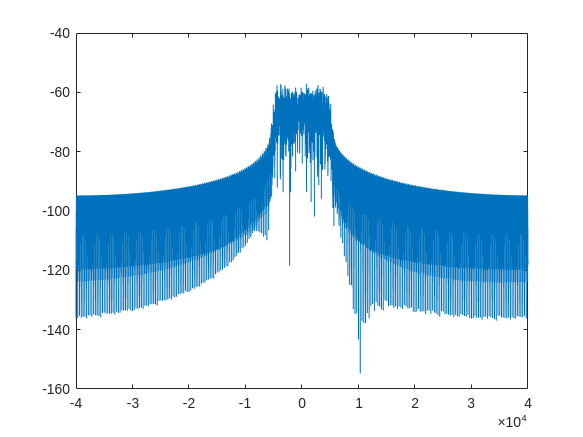


% get the spectrum of the concatednated signal
[f_upsamp_all, spec_upsamp_all] = GetSpectrum(s_t_upsamp_vec,OFDM_samplerate_upsamp);
mag_spec_upsam_all = 20*log10(abs(spec_upsamp_all));

% plot the spectrum of the upsampled signal
figure(2)
clf
plot(f_upsamp_all,mag_spec_upsam_all)